**Problem 6. 2D Schrodinger solver**

*Rewrite the 1D Schrodiner equation solver to solve two-dimensional (possibly 3D) problems. Solve*

*a) a two dimensional potential box – and check the results against the analytical formula.*

Mivel a példában szereplő a differenciálegyenlet szeparábilis, ezért először így oldottam meg a problémát: $\psi \left(x,y\right)=X\left(x\right)Y\left(y\right)\ldotp$

Először megoldottam x-re, felírtam a Hamilton operátort mátrix alakban, és ennek kerestem a sajátértékeit és sajátvektorait, majd ugyanezt kiszámítottam y-ra is. A két eredmény megfelelő sajátvektorait összeszoroztam, így megkaptam a Schrödinger egyenlet megoldásait. Ez jó összehasonlítási alapnak szolgált a bonyolultabban implementált 2D Schrödinger megoldóhoz.

[https://chem.libretexts.org/Bookshelves/Physical_and_Theoretical_Chemistry_Textbook_Maps/Supplemental_Modules_(Physical_and_Theoretical_Chemistry)/Quantum_Mechanics/05.5%3A_Particle_in_Boxes/Particle_in_a_2-Dimensional_Box](https://chem.libretexts.org/Bookshelves/Physical_and_Theoretical_Chemistry_Textbook_Maps/Supplemental_Modules_(Physical_and_Theoretical_Chemistry)/Quantum_Mechanics/05.5%3A_Particle_in_Boxes/Particle_in_a_2-Dimensional_Box)

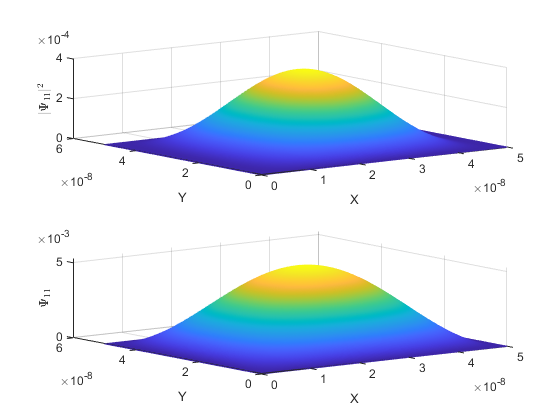

clear variables; close all;

%Charge of the electron
q_e = 1.602e-19;

%Weight of the electron
m_e = 9.109e-31;

%Planc constant
h = 1.054572e-34;

%The value of h^2/2m
h_ = -h^2/(2.0*m_e);

%Length of the observed region
TotalLength = 5e-8;
%Resolution of the observed region
N = 400;

%Height of the potential wall confining the electron
Wallenergy = 100*q_e;
WallWidth = 10;

%Place the coordinate system
[X,Y] = meshgrid(linspace(0, TotalLength, N));
%Resolution
dx = TotalLength/N;
dy= TotalLength/N;

%a)

%Potential: V = V0 eV
V(1:N, 1:N) = 0.0;
V(1:WallWidth, :) = Wallenergy;
V(:, N-WallWidth:N) = Wallenergy;
V(:, 1:WallWidth) = Wallenergy;
V(N-WallWidth:N, :) = Wallenergy;

H = zeros(N,N);
for i = 2 : N-1
    H(i,i) = -2.0*h_/dx^2 + V(i, i);
    H(i,i-1) = h_/dx^2;
    H(i,i+1) = h_/dx^2;
end

%The sides of the matrix:
%Left side:
H(1,1) = -2.0*h_/dx^2 + V(1, 1);
H(1,2) = h_/dx^2;

%Right side:
H(N,N) = -2.0*h_/dx^2 + V(N, N);
H(N,N-1) =h_/dx^2;
[Psi,Emx] = eig(H);

%Makes a one-dimensional list from the energy matrix
E = zeros(1, N);

for i = 1:N
    E(i) = Emx(i,i);
end

%Finds the first n minimum-energy eigenvalue
n = 4;
E_minValue = zeros(n);

%Finds the minimum-energy eigenvalue
[MinE,MinEindex] = min(E);
MinE;
Psi_n(:,1) = Psi(:,MinEindex);
E_minValue(1) = MinE;

for i=2:n
    E(MinEindex) = E(MinEindex)+Wallenergy;
    [MinE,MinEindex] = min(E);
    Psi_n(:,i) = Psi(:,MinEindex);
    E_minValue(i) = MinE;
end

Hy = zeros(N,N);
for i = 2 : N-1
    Hy(i,i) = -2.0*h_/dy^2 + V(i, i);
    Hy(i,i-1) = h_/dy^2;
    Hy(i,i+1) = h_/dy^2;
end

%The sides of the matrix:
%Left side:
Hy(1,1) = -2.0*h_/dy^2 + V(1, 1);
Hy(1,2) = h_/dy^2;

%Right side:
Hy(N,N) = -2.0*h_/dy^2 + V(N, N);
Hy(N,N-1) =h_/dy^2;

[Psiy,Emxy] = eig(H);

%Makes a one-dimensional list from the energy matrix
Ey = zeros(1, N);

for i = 1:N
    Ey(i) = Emxy(i,i);
end

%Finds the first n minimum-energy eigenvalue
Ey_minValue = zeros(n);

%Finds the minimum-energy eigenvalue
[MinEy,MinEindexy] = min(Ey);
MinEy;
Psi_ny(:,1) = Psiy(:,MinEindexy);
Ey_minValue(1) = MinEy;

for i=2:n
    Ey(MinEindexy) = Ey(MinEindexy)+Wallenergy;
    [MinEy,MinEindexy] = min(Ey);
    Psi_ny(:,i) = Psiy(:,MinEindexy);
    Ey_minValue(i) = MinEy;
end

figure(11);
subplot(2, 1, 1);
mesh(X, Y ,abs(Psi_n(:,1).*transpose(Psi_ny(:,1)).^2));
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{11}|^2$', 'Interpreter',"latex");


subplot(2, 1, 2);
mesh(X, Y ,Psi_n(:,1).*transpose(Psi_ny(:,1)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{11}$', 'Interpreter',"latex");

E11 = (E_minValue(1, 1)+Ey_minValue(1, 1))/q_e

E11 = 3.3329e-04


figure(12);
subplot(2, 2, 1);
mesh(X, Y ,abs(Psi_n(:,1).*transpose(Psi_ny(:,2))).^2);
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{12}|^2$', 'Interpreter',"latex");

subplot(2, 2, 2);
mesh(X, Y ,Psi_n(:,1).*transpose(Psi_ny(:,2)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{12}$', 'Interpreter',"latex");
E12=(E_minValue(1, 1)+Ey_minValue(2, 1))/q_e

E12 = 8.3321e-04

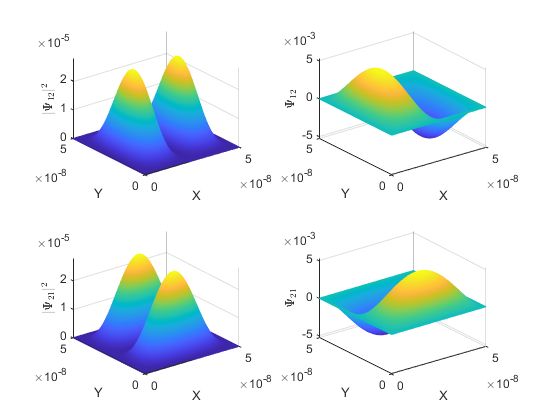



subplot(2, 2, 3);
mesh(X, Y ,abs(Psi_n(:,2).*transpose(Psi_ny(:,1))).^2);
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{21}|^2$', 'Interpreter',"latex");

subplot(2, 2, 4);
mesh(X, Y ,Psi_n(:,2).*transpose(Psi_ny(:,1)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{21}$', 'Interpreter',"latex");

E21=(E_minValue(2, 1)+Ey_minValue(1, 1))/q_e

E21 = 8.3321e-04

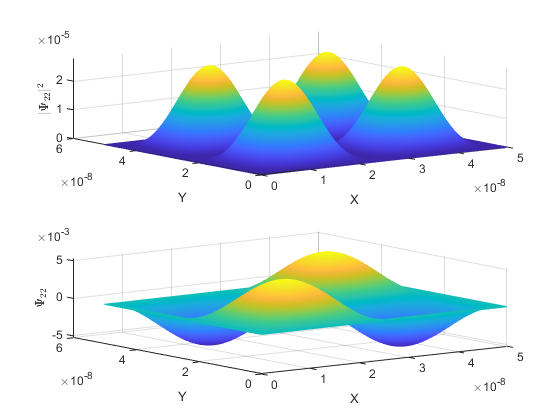


figure(22);
subplot(2 ,1, 1);
mesh(X, Y ,abs(Psi_n(:,2).*transpose(Psi_ny(:,2))).^2);
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{22}|^2$', 'Interpreter',"latex");

subplot(2 ,1, 2);
mesh(X, Y ,Psi_n(:,2).*transpose(Psi_ny(:,2)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{22}$', 'Interpreter',"latex");

E22=(E_minValue(2, 1)+Ey_minValue(2, 1))/q_e

E22 = 0.0013


figure(13);
subplot(2, 2, 1);
mesh(X, Y ,abs(Psi_n(:,1).*transpose(Psi_ny(:,3))).^2);
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{13}|^2$', 'Interpreter',"latex");

subplot(2, 2, 2);
mesh(X, Y ,Psi_n(:,1).*transpose(Psi_ny(:,3)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{13}$', 'Interpreter',"latex");
E13=(E_minValue(1, 1)+Ey_minValue(3, 1))/q_e

E13 = 0.0017

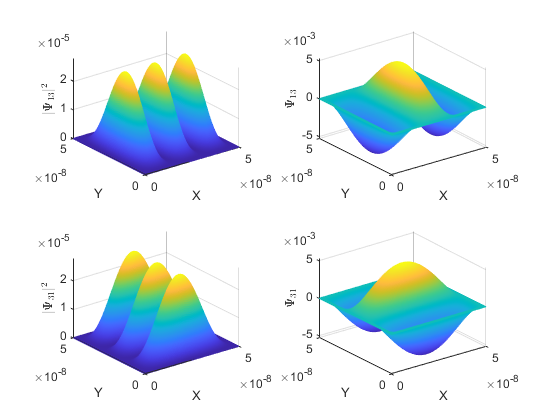


subplot(2, 2, 3);
mesh(X, Y ,abs(Psi_n(:,3).*transpose(Psi_ny(:,1))).^2);
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{31}|^2$', 'Interpreter',"latex");

subplot(2, 2, 4);
mesh(X, Y ,Psi_n(:,3).*transpose(Psi_ny(:,1)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{31}$', 'Interpreter',"latex");

E31=(E_minValue(3, 1)+Ey_minValue(1, 1))/q_e

E31 = 0.0017


figure(15);
subplot(2, 2, 1);
mesh(X, Y ,abs(Psi_n(:,2).*transpose(Psi_ny(:,3))).^2);
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{23}|^2$', 'Interpreter',"latex");


subplot(2, 2, 2);
mesh(X, Y ,Psi_n(:,2).*transpose(Psi_ny(:,3)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{23}$', 'Interpreter',"latex");
E23=(E_minValue(2, 1)+Ey_minValue(3, 1))/q_e

E23 = 0.0022

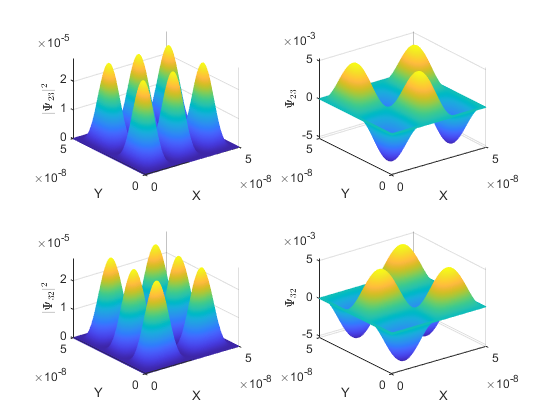


subplot(2, 2, 3);
mesh(X, Y ,abs(Psi_n(:,3).*transpose(Psi_ny(:,2))).^2);
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{32}|^2$', 'Interpreter',"latex");

subplot(2, 2, 4);
mesh(X, Y ,Psi_n(:,3).*transpose(Psi_ny(:,2)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{32}$', 'Interpreter',"latex");

E32=(E_minValue(3, 1)+Ey_minValue(2, 1))/q_e

E32 = 0.0022

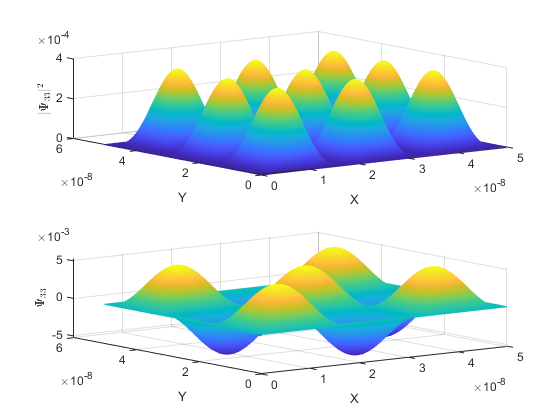


figure(34);
subplot(2, 1, 1);
mesh(X, Y ,abs(Psi_n(:,3).*transpose(Psi_ny(:,3)).^2));
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{33}|^2$', 'Interpreter',"latex");

subplot(2, 1, 2);
mesh(X, Y ,Psi_n(:,3).*transpose(Psi_ny(:,3)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{33}$', 'Interpreter',"latex");

E33=(E_minValue(3, 1)+Ey_minValue(3, 1))/q_e

E33 = 0.0030

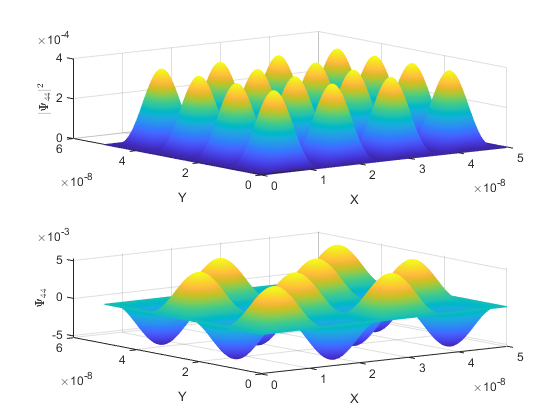


figure(44);
subplot(2, 1, 1);
mesh(X, Y ,abs(Psi_n(:,4).*transpose(Psi_ny(:,4)).^2));
xlabel('X');
ylabel('Y');
zlabel('$|\Psi_{44}|^2$', 'Interpreter',"latex");

subplot(2, 1, 2);
mesh(X, Y ,Psi_n(:,4).*transpose(Psi_ny(:,4)));
xlabel('X');
ylabel('Y');
zlabel('$\Psi_{44}$', 'Interpreter',"latex");

E44=(E_minValue(4, 1)+Ey_minValue(4, 1))/q_e

E44 = 0.0053

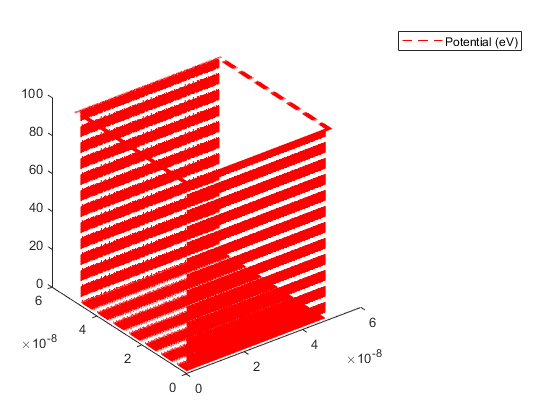


figure;
title('Potential');
plot3(X,Y, V/q_e,'r--');
legend('Potential (eV)');
hold off;

A következő szekcióban általánosítottam a Schrödinger megoldót. Itt már nem feltétel, hogy csak x-től, vagy csak y-tól függjön a potenciál értéke. Az interneten találtam a 2D-s probléma megoldására a Kronecker sum műveletet, először kipróbáltam "kicsiben", úgy találtam, hogy működik, így ezzel oldottam meg a problémát, és a dimenzió növelést. $\frac{d^2 }{{\textrm{dx}}^2 }\approx D_{x\;}$és $\frac{d^2 }{{\textrm{dy}}^2 }\approx D_y \ldotp$ 

1D-ben (3x3):  $\frac{1}{\Delta x^2} \cdot$$\left\lbrack \begin{array}{ccc}
-2 & 1 & 0\\
1 & -2 & 1\\
0 & 1 & -2
\end{array}\right\rbrack$$=D_x$. 2D-ben (Kronecker product): $I\otimes D_x =\frac{1}{\Delta x^2 }\cdot$$\left\lbrack \begin{array}{ccccccccc}
-2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & -2 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & -2 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & -2 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & -2 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2
\end{array}\right\rbrack$, 

$\frac{1}{\Delta y^2} \cdot$$\left\lbrack \begin{array}{ccc}
-2 & 1 & 0\\
1 & -2 & 1\\
0 & 1 & -2
\end{array}\right\rbrack$$=D_y$, és 2D-ben: $D_y \otimes I=\frac{1}{\Delta y^2 }\cdot \left\lbrack \begin{array}{ccccccccc}
-2 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\
0 & -2 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & -2 & 0 & 0 & 1 & 0 & 0 & 0\\
1 & 0 & 0 & -2 & 0 & 0 & 1 & 0 & 0\\
0 & 1 & 0 & 0 & -2 & 0 & 0 & 1 & 0\\
0 & 0 & 1 & 0 & 0 & -2 & 0 & 0 & 1\\
0 & 0 & 0 & 1 & 0 & 0 & -2 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0 & 0 & -2 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & -2
\end{array}\right\rbrack$.

És a kronecker sum a következő: $\frac{d^2 }{{\textrm{dx}}^2 }+$$\frac{d^2 }{{\textrm{dy}}^2 }$ = $I\otimes D_x$+ $D_y \otimes I=D\oplus D\ldotp$ Ezt alkalmaztam "nagyban" az egyenlet megoldása során. Egy szokatlan dolgot tapasztaltam, ha a kronecker sum-ban a kronecker product-okat eltérő súllyal veszem, akkor kapok a potenciál dobozra irányban "megfelelő" megoldást, ha ugyanolyan súllyal veszem, akkor egy 45 fokkal elforgatott megoldást kapok. Ennek az okára nem jöttem rá.

Az eredeti Schrödinger egyenlet: $-\frac{\hbar^2 }{2m}\left(\frac{d^2 }{{\textrm{dx}}^2 }+\frac{d^2 }{{\textrm{dy}}^2 }\right)\Psi +V\Psi =E\Psi$ átírva: $\left\lbrack -\frac{\hbar^2 }{2m}\left(D\oplus D\right)+V\cdot I\right\rbrack \Psi =E\Psi$. Az így kapott $\left(D\oplus D\right)$mátrix mérete $N^2 {\textrm{xN}}^2$ lesz, ennek megfelelően a potenciált is átméreteztem $N^2 {\textrm{xN}}^2$-re úgy, hogy csak a diagonálisban találhatók 0-tól különböző potenciál értékek. A kódban található, ahogy definiáltam ezeket a mátrixokat. Erre megoldva a sajátérték problémát, nagyon hasonló hullámfüggvényeket kaptam megoldásnak, mint az analitikus, mint a szeparábilis változókkal megoldott differenciálegyenlet megoldásai.

[https://en.wikipedia.org/wiki/Kronecker_sum_of_discrete_Laplacians](https://en.wikipedia.org/wiki/Kronecker_sum_of_discrete_Laplacians)

[https://physics.stackexchange.com/questions/292492/finite-difference-method-applied-to-the-2d-time-independent-schr%C3%B6dinger-equation](https://physics.stackexchange.com/questions/292492/finite-difference-method-applied-to-the-2d-time-independent-schr%C3%B6dinger-equation)

clear variables;
n=18;                   % number of solution
%Charge of the electron
q_e = 1.602e-19;
%Weight of the electron
m_e = 9.109e-31;
%Planc constant
h = 1.054572e-34;
%The value of h^2/2m
h_ = h^2/(2.0*m_e);
%Vacuum permittivity
%Length of the observed region
TotalLength = 5e-8;
%Resolution of the observed region
N = 70;

Wallenergy = 100*q_e;
WallWidth = 10;
x=linspace(0,TotalLength,N);
y=linspace(0,TotalLength,N);

%Place the coordinate system
[X,Y] = meshgrid(x, y);
%Resolution
dx = TotalLength/N;
dy= TotalLength/N;


V(1:N, 1:N) = 0.0;
V(1:WallWidth, :) = Wallenergy;
V(:, N-WallWidth:N) = Wallenergy;
V(:, 1:WallWidth) = Wallenergy;
V(N-WallWidth:N, :) = Wallenergy;

Dx = zeros(N, N);
for i = 2 : N-1
    Dx(i,i) = -2.0*h_/dx^2;
    Dx(i,i-1) = 1*h_/dx^2;
    Dx(i,i+1) = 1*h_/dy^2;
end
a1=1;
a2=0.95;
%The sides of the matrix:
%Left side:
Dx(1,1) = -2*h_/dx^2;
Dx(1,2) = 1*h_/dx^2;
%Right side: Psi(PrSize+1)=0
Dx(N, N)= -2*h_/dx^2;
Dx(N, N-1)= 1*h_/dx^2;

Dy = zeros(N, N);
for i = 2 : N-1
    Dy(i,i) = -2.0*h_/dy^2;
    Dy(i,i-1) = 1*h_/dy^2;
    Dy(i,i+1) = 1*h_/dy^2;
end

%The sides of the matrix:
%Left side:
Dy(1,1) = -2*h_/dy^2;
Dy(1,2) = 1*h_/dy^2;
%Right side: Psi(PrSize+1)=0
Dy(N, N)= -2*h_/dy^2;
Dy(N, N-1)= 1*h_/dy^2;

%kronsum
%T=-0.5*((kron(D,eye(size(D,2))) + kron(eye(size(D,2)),D)));
T = -0.5*((a1*kron(Dy, speye(N))) + a2*kron(speye(N), Dx)) ;
U=diag(reshape(V, N^2, 1));
H=T+U;
[Psi,Emx] = eig(H);

%Makes a one-dimensional list from the energy matrix
E = zeros(1, N);
for i = 1:N
    E(i) = Emx(i,i);
end
%Finds the first n minimum-energy eigenvalue
E_minValue = zeros(n);
%Finds the minimum-energy eigenvalue
[MinE,MinEindex] = min(E);
MinE;
Psi_n(:, :,1) = reshape(transpose(Psi(:,MinEindex)), N, N);
E_minValue(1) = MinE;
for i=2:n
    E(MinEindex) = E(MinEindex)+Wallenergy;
    [MinE,MinEindex] = min(E);
    Psi_n(:,:,i) = reshape(transpose(Psi(:,MinEindex)), N, N);
    E_minValue(i) = MinE;
end

Energy=transpose(E_minValue(1:9, 1)./q_e)

Energy =     0.0003    0.0007    0.0007    0.0011    0.0014    0.0015    0.0018    0.0019    0.0024


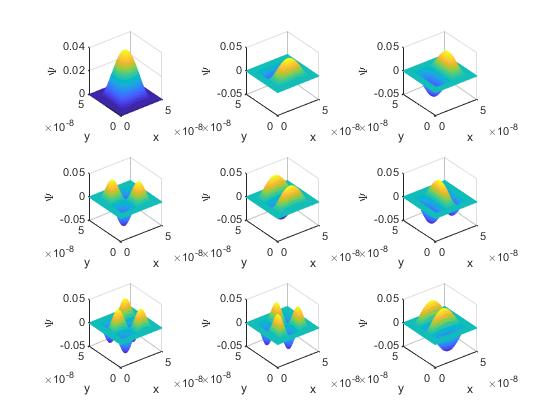

figure(2);
for i=1:9
    subplot(3,3, i);
    mesh(X, Y, Psi_n(:,:,i));
    xlabel('x');
    ylabel('y');
    zlabel('$\Psi$', 'Interpreter',"latex");
end


Energy=transpose(E_minValue(10:18, 1)./q_e)

Energy =     0.0025    0.0026    0.0028    0.0029    0.0036    0.0036    0.0036    0.0038    0.0041


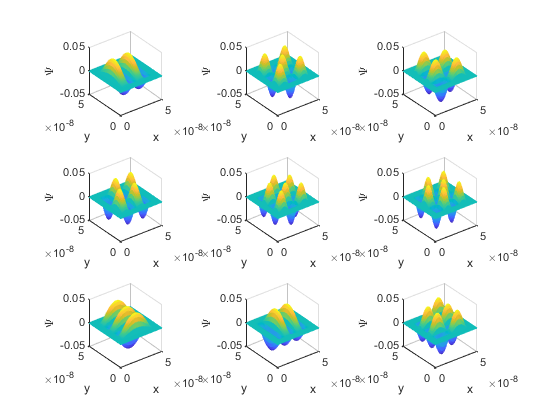


figure(3);
for i=10:18
    subplot(3,3, i-9);
    mesh(X, Y, Psi_n(:,:,i));
    xlabel('x');
    ylabel('y');
    zlabel('$\Psi$', 'Interpreter',"latex");
end

Analitikus megoldás:

figure(9);

L=1;
x=linspace(0,L,N);
y=linspace(0,L,N);

[X,Y] = meshgrid(x, y);

"Analytical solution"

ans = "Analytical solution"

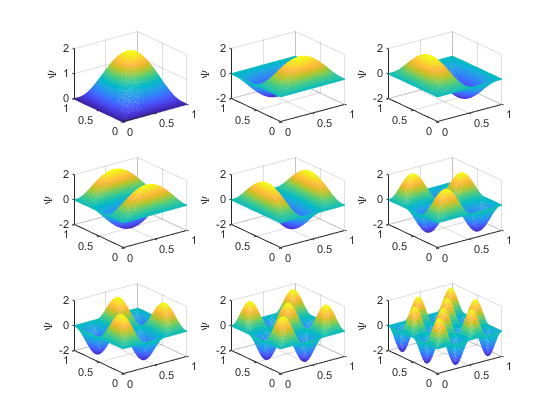


subplot(3,3,1);
PSI11= 2/((L^2)^0.5).*sin((1*pi/L).*X).*sin((1*pi/L).*Y);
mesh(X, Y, PSI11);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,2);
PSI12= 2/((L^2)^0.5).*sin((1*pi/L).*X).*sin((2*pi/L).*Y);
mesh(X, Y, PSI12);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,3);
PSI21= 2/((L^2)^0.5).*sin((2*pi/L).*X).*sin((1*pi/L).*Y);
mesh(X, Y, PSI21);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,4);
PSI13= 2/((L^2)^0.5).*sin((1*pi/L).*X).*sin((3*pi/L).*Y);
mesh(X, Y, PSI13);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,5);
PSI31= 2/((L^2)^0.5).*sin((3*pi/L).*X).*sin((1*pi/L).*Y);
mesh(X, Y, PSI31);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,6);
PSI23= 2/((L^2)^0.5).*sin((2*pi/L).*X).*sin((3*pi/L).*Y);
mesh(X, Y, PSI23);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,7);
PSI32= 2/((L^2)^0.5).*sin((3*pi/L).*X).*sin((2*pi/L).*Y);
mesh(X, Y, PSI32);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,8);
PSI33= 2/((L^2)^0.5).*sin((3*pi/L).*X).*sin((3*pi/L).*Y);
mesh(X, Y, PSI33);
zlabel('$\Psi$', 'Interpreter',"latex");

subplot(3,3,9);
PSI44= 2/((L^2)^0.5).*sin((4*pi/L).*X).*sin((4*pi/L).*Y);
mesh(X, Y, PSI44);
zlabel('$\Psi$', 'Interpreter',"latex");

Az analitikus megoldás kis mérettartományban nagyságrendekkel eltérő függvényeket eredményez.

*b) a two-dimensional Hydrogen atom*

Ezt a problémát ugyanúgy oldottam meg, mint az a) feladatot. A potenciál és az ábrázolásmódban van csak különbség, illetve itt sparse mátrixokkal számoltam. Bevezettem a Coulomb potenciált, és minden pontban kiszámítottam a potenciál értéket (mátrix) r függvényében, illetve a potenciálgát nem négyzetes, hanem "kör alakú" (Bohr sugár: $$$R=5.29 \cdot 10^{-11}$$$ m). Az energiaértékek nagyon kicsik lettek. Erre azt a magyarázatot találtam, hogy a vizsgált tartomány növelésével és csökkentésével változnak az energiaszintek. Ha elegendően nagy tartományon számítottam ki a Schrödinger egyenlet megoldását, a várt energiaszinthez közeli eredményt hozták. Ezt a megoldást azért nem alkalmaztam, mert az ábrázolásnál nagyon pontatlan ábrát kaptam, hiszen a felbontást nem tudtam növelni, mert elérte a Matlab számítási határait még sparse mátrixokkal is (210*210 x 210*210 = 44100 x 44100 mátrix volt a legnagyobb, ami lefutott).

clear variables;

n=16;                   % number of solution
%Charge of the electron
q_e = -1.602e-19;
%Weight of the electron
m_e = 9.109e-31;
%Planc constant
h = 1.054572e-34;
%The value of h^2/2m
h_ = -h^2/(2.0*m_e);
%Vacuum permittivity
eps0 = 8.854187e-12;
%Length of the observed region
TotalLength = 3*5.29e-11;
%Resolution of the observed region
N = 120;
k_e=1/(4*pi*eps0);

Wallenergy = -300*q_e;

x=linspace(-TotalLength/2,TotalLength/2,N);
y=linspace(-TotalLength/2,TotalLength/2,N);

%Place the coordinate system in the middle (0 is in the middle)
[X,Y] = meshgrid(x, y);
%Resolution
dx = TotalLength/N;
dy= TotalLength/N;


R=5.29e-11;      % r_x
x0=0; y0=0;      % center

r0=5.29e-11;

idx=((X-x0)/R).^2 + ((Y-y0)/R).^2 < 1;

Vb=-300*q_e;                 % Potential barrier

V=zeros(N, N);
Vp=zeros(N, N);

for i=1:N
    for j=1:N
        r_=sqrt(x(i)^2+y(j)^2);
            if r_==0
                Va=(-k_e*q_e^2)/(1e-12);
            else
                Va=-k_e*q_e^2/r_;
            end
        Vp(i, j)= Va;
    end
end

V=(idx)*0 + (1-idx)*Vb;

V=V+Vp;

Dx = zeros(N, N);

for i = 2 : N-1
    Dx(i,i) = -2.0*h_/dx^2;
    Dx(i,i-1) = 1*h_/dx^2;
    Dx(i,i+1) = 1*h_/dx^2;
end

a1=1;
a2=0.95;
%The sides of the matrix:
%Left side:
Dx(1,1) = -2*h_/dx^2;
Dx(1,2) = 1*h_/dx^2;

%Right side:
Dx(N, N)= -2*h_/dx^2;
Dx(N, N-1)= 1*h_/dx^2;

Dy = zeros(N, N);

for i = 2 : N-1
    Dy(i,i) = -2.0*h_/dy^2;
    Dy(i,i-1) = 1*h_/dy^2;
    Dy(i,i+1) = 1*h_/dy^2;
end

%The sides of the matrix:
%Left side:
Dy(1,1) = -2*h_/dy^2;
Dy(1,2) = 1*h_/dy^2;

%Right side:
Dy(N, N)= -2*h_/dy^2;
Dy(N, N-1)= 1*h_/dy^2;

Dy=sparse(Dy);

%kronsum
T =-0.5*((kron(Dy, speye(N))) + kron(speye(N), Dx));

T = sparse(T);

U=diag(reshape(V, N^2, 1));
U = sparse(U);

H=T+U;
[Psi,Emx] = eigs(H, N);

%Makes a one-dimensional list from the energy matrix
E = zeros(1, N);

for i = 1:N
    E(i) = Emx(i,i);
end

%Finds the first n minimum-energy eigenvalue
E_minValue = zeros(n);

%Finds the minimum-energy eigenvalue
[MinE,MinEindex] = min(E);
MinE;
Psi_n(:, :,1) = reshape(transpose(Psi(:,MinEindex)), N, N);
E_minValue(1) = MinE;

for i=2:n
    E(MinEindex) = E(MinEindex)+Wallenergy;
    [MinE,MinEindex] = min(E);
    Psi_n(:,:,i) = reshape(transpose(Psi(:,MinEindex)), N, N);
    E_minValue(i) = MinE;
end

Energy= transpose(E_minValue(1:6, 1))./(-q_e) %meV

Energy = 	1.0e+04 *

   -8.7246   -8.7123   -8.7123   -8.7090   -8.7054   -8.7054


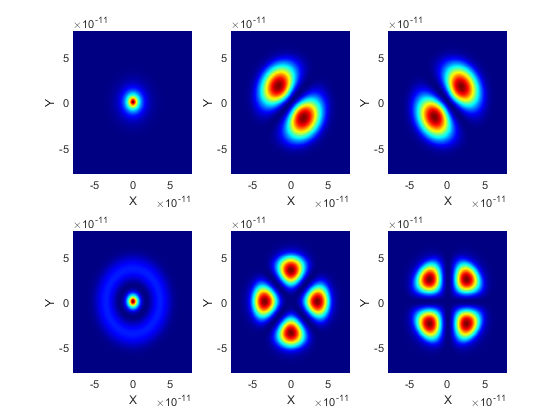


figure(4);
for i=1:6
    subplot(2, 3, i);
    pcolor(X, Y, abs(Psi_n(:,:,i)).^2);
    xlabel('X')
    ylabel('Y')
    %axis equal
    shading flat
    colormap(jet)
end


Energy=transpose(E_minValue(7:12, 1))./(-q_e) %eV

Energy = 	1.0e+04 *

   -8.6979   -8.6979   -8.6965   -8.6965   -8.6946   -8.6896


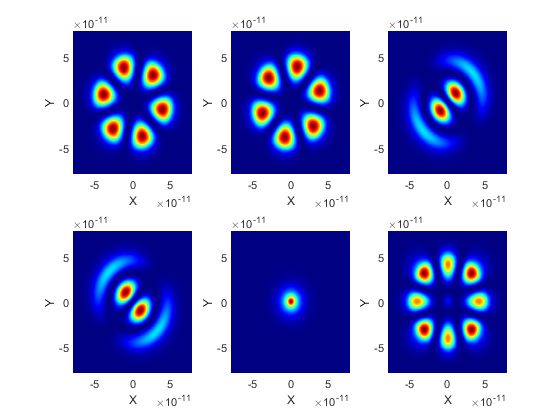


figure(5);
for i=7:12
    subplot(2, 3, i-6);
    pcolor(X, Y, abs(Psi_n(:,:,i)).^2);
    xlabel('X')
    ylabel('Y')
    %axis equal
    shading flat
    colormap(jet)
end


Energy=transpose(E_minValue(13:16, 1))./(-q_e) %eV

Energy = 	1.0e+04 *

   -8.6895   -8.6893   -8.6861   -8.6858


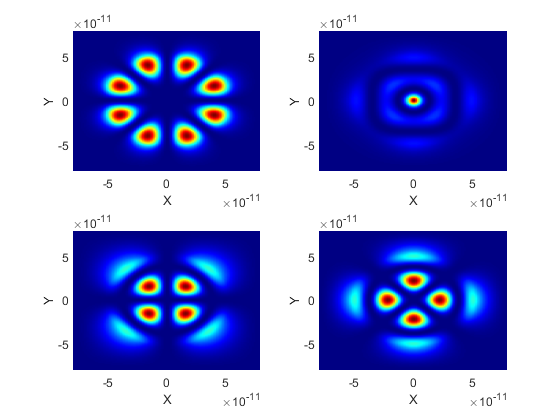


figure(6);
for i=13:16
    subplot(2, 2, i-12);
    pcolor(X, Y, abs(Psi_n(:,:,i)).^2);
    xlabel('X')
    ylabel('Y')
    %axis equal
    shading flat
    colormap(jet)
end

***Készítette: Bánkövi Orsolya, DAZOJ8***